%~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% MakeEmilysPlot.m
%
% Can you make a scatter plot with N2 (or dTdz) on one axis, log10(chi) on a second axis, and color by the gamma (or log10 gamma) needed to have eps_chi=eps? Sorry I am stuck on the stratification piece. (Patches clumping so strongly at 1 m does seem like it might be problematic.)
%
% * Note: I think the scatter plots are misleading, because there are too
% many points. See the 2D histograms further down, these should be more
% accurate.
%
%
%-------------------
%  10/05/16 - A.Pickering - andypicke@gmail.com
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~

clear ; close all

% load EQ14 data
dir_base='/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/Data/chameleon/processed';
clear cham
load( fullfile( dir_base, '/Cstar=0_01366/sum/eq14_sum.mat') )

% throw out epsilon below noise floor
ib=find(log10(cham.EPSILON)<-8);
cham.EPSILON(ib)=nan;

% find points not in mixed layer or near bottom of profiles
ig=find(cham.P>60 & cham.P<180);

n2=cham.N2(ig);
dtdz=cham.DTDZ_RHOORDER(ig);
chi=cham.CHI(ig);
eps=cham.EPSILON(ig);

% gamma using all data points
%gam_cham=cham.N2 .* cham.CHI ./2 ./ cham.EPSILON ./ (cham.DTDZ.^2);
gam_cham=n2 .* chi ./2 ./ eps ./ (dtdz.^2);
%

## Plot 2D histograms of gamma vs each variable

figure(1);clf
agutwocolumn(1)
wysiwyg

yl=[-6 2];
yl=[-5 1];
%yl=[-3 0]

ax1=subplot(221);
histogram2(real(log10(n2)),log10(gam_cham),200,'DisplayStyle','tile')
xlabel('log_{10}N^2','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
colorbar
ylim(yl)
xlim([-6 -2])
hold on
xvec=linspace(-6,-2,100);
plot(xvec,xvec+2,'k--')

ax1.XTick=[-6:-2];
ax1.YTick=yl(1):yl(2);

ax2=subplot(222);
histogram2(real(log10(dtdz)),log10(gam_cham),200,'DisplayStyle','tile')
xlabel('log_{10}dT/dz','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
colorbar
ylim(yl)
xlim([-4 -0])
ax2.XTick=[-4:0];
ax1.YTick=yl(1):yl(2);
hold on
xvec=linspace(-4,0,100);
plot(xvec,xvec,'k--')


ax3=subplot(223);
histogram2(real(log10(chi)),log10(gam_cham),200,'DisplayStyle','tile')
xlabel('log_{10}\chi','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
colorbar
ylim(yl)
xlim([-12 -4])
ax3.XTick=[-12:-4];
ax1.YTick=yl(1):yl(2);

hold on
xvec=linspace(-12,-4,100);
plot(xvec,xvec+6,'k--')


ax4=subplot(224);
h=histogram2(real(log10(eps)),log10(gam_cham),200,'DisplayStyle','tile');
xlabel('log_{10}\epsilon','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
colorbar
ylim(yl)
xlim([-8 -5])
ax4.XTick=[-8:-5];
ax1.YTick=yl(1):yl(2);

hold on
xvec=linspace(-8,-5,100);
plot(xvec,xvec+4,'k--')

linkaxes([ax1 ax2 ax3 ax4],'y')
%
%figdir='/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/mfiles/Patches'

figdir = /Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/mfiles/Patches

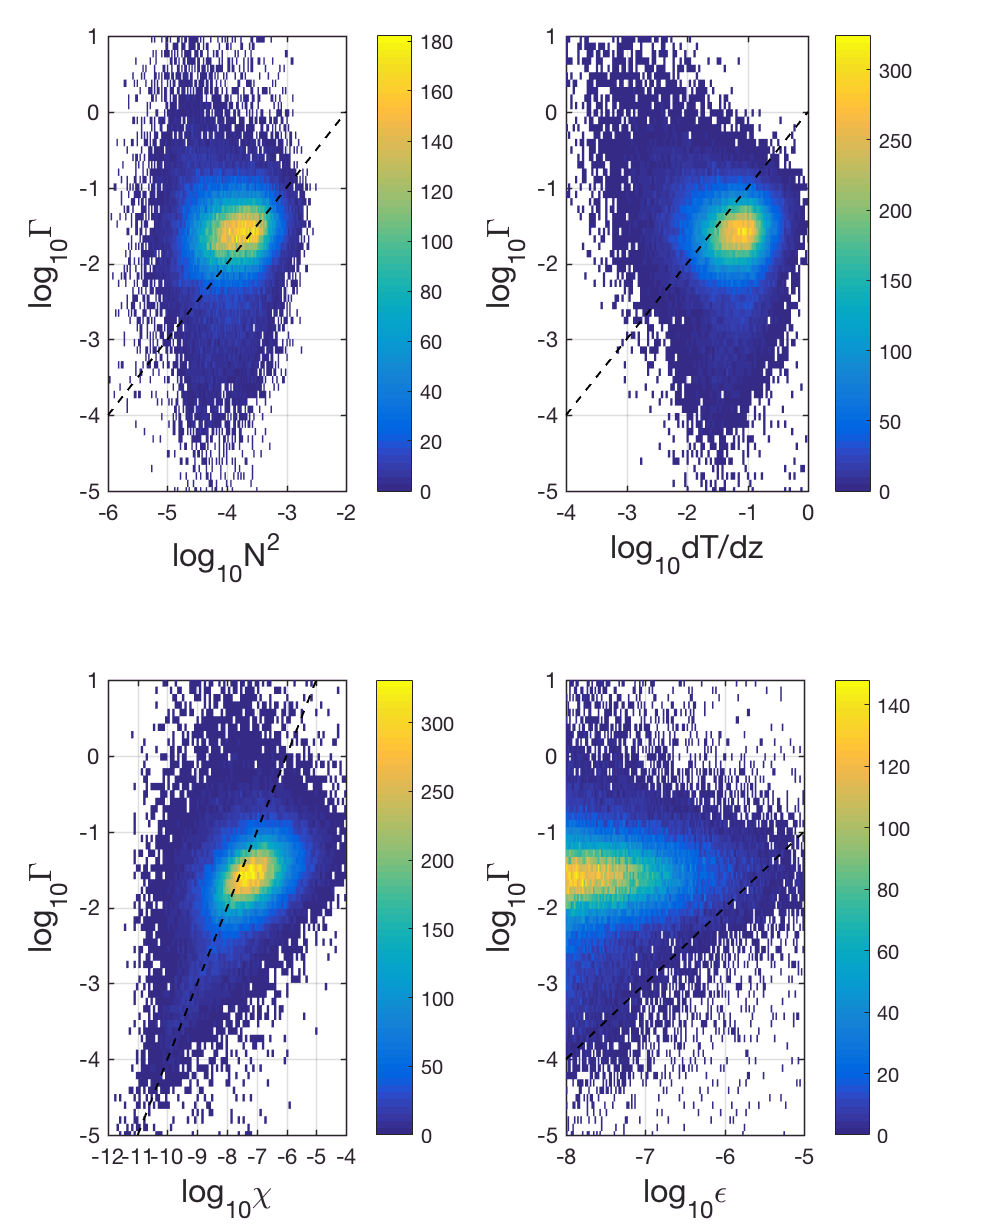

%print( fullfile( figdir,'2X2_2dhist_Gamma'), '-dpng')

## try binning gamma by N^2 and chi

% brute force method (there has to be some better way of doing this?)

dchi=logspace(-12,-4,100); % make different lengths so we can't confuse axes
dN=logspace(-6,-2.5,95);
mean_gamma=nan*ones(length(dchi)-1,length(dN)-1);
median_gamma=mean_gamma;
for m=1:length(dchi)-1;
        for n=1:length(dN-1)-1;
            clear ind
                ind=find( n2>dN(n) & n2<dN(n+1) & chi>dchi(m) & chi<dchi(m+1) );
                mean_gamma(m,n)=nanmean(gam_cham(ind));
                median_gamma(m,n)=nanmedian(gam_cham(ind));
        end
end

%


figure(1);clf
agutwocolumn(1)
wysiwyg

subplot(211)
pcolor(log10(dN(1:end-1)),log10(dchi(1:end-1)),mean_gamma)
shading flat
caxis([0 0.1])
cb=colorbar;
cb.Label.String='\Gamma';
ylabel('log_{10}\chi','fontsize',16)
xlabel('log_{10}N^2','fontsize',16)
grid on
title('mean gamma') 

subplot(212)
pcolor(log10(dN(1:end-1)),log10(dchi(1:end-1)),median_gamma)
shading flat
caxis([0 0.11])
cb=colorbar;
cb.Label.String='\Gamma';
ylabel('log_{10}\chi','fontsize',16)
xlabel('log_{10}N^2','fontsize',16)
grid on
title('median gamma')

%figdir='/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/mfiles/Patches'

figdir = /Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/mfiles/Patches

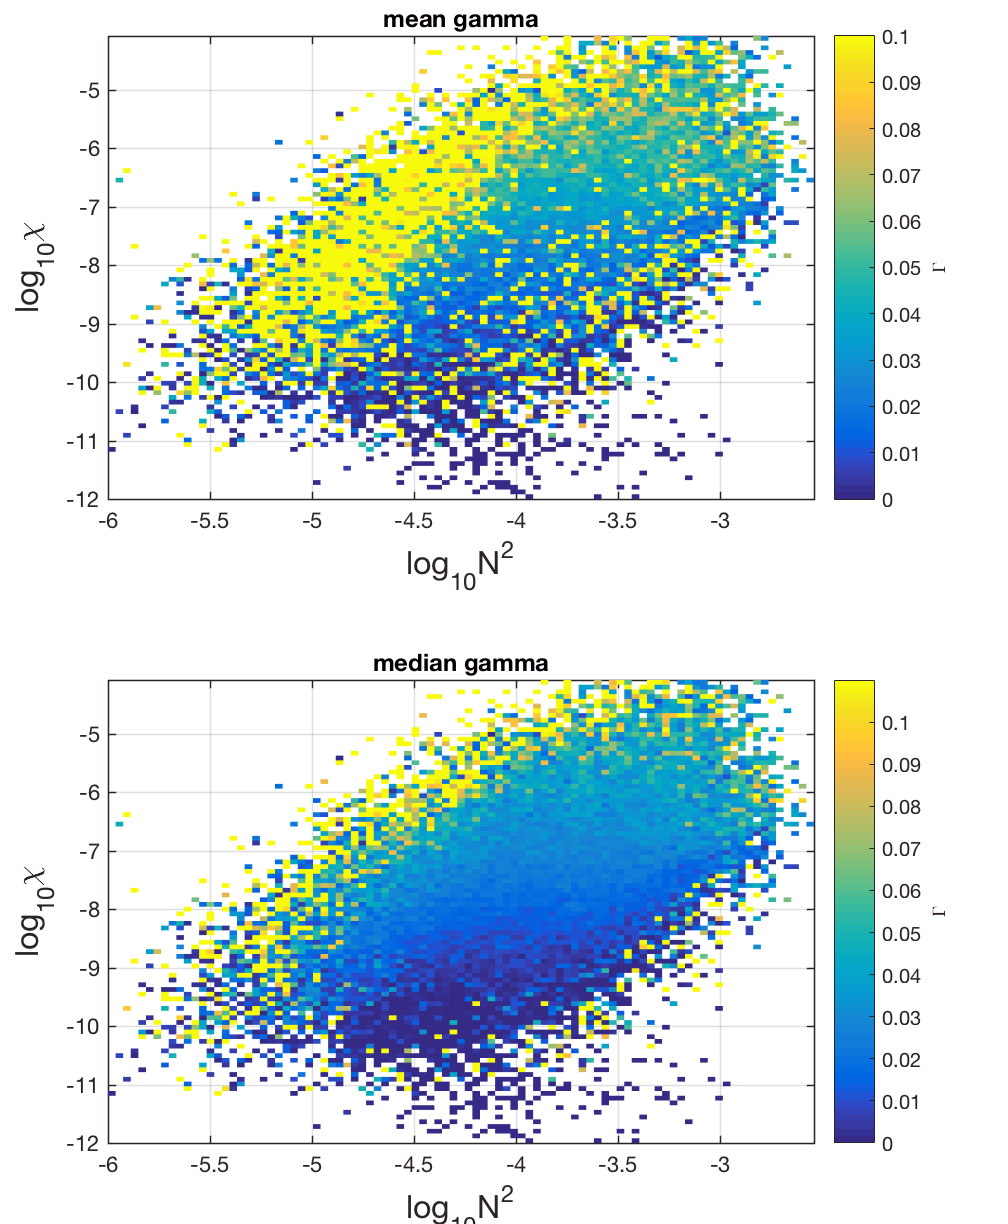

%print( fullfile( figdir,'Gamma_binnedBy_N2_chi'), '-dpng')